# Example how to use functions from MLIB/CRS library

**Author**: Abakumov Ivan

**University of Hamburg**

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

**Publication date**: 31st August 2016

Library MLIB/CRS includes codes that allow:

- to compute analytically traveltime of reflection waves for a number of models;

- to compute wavefield attributes associated with the central ray;

- to compute traveltime corrections as predicted by CRS, DSR, nCRS and i-CRS approximations (both matlab and C++ realizations)

See detailed explanation in Chapter 3, Abakumov, I. (2017). Systematic analysis of double-square-root-based stacking operators

[http://ediss.sub.uni-hamburg.de/volltexte/2017/8302/pdf/Dissertation.pdf](http://ediss.sub.uni-hamburg.de/volltexte/2017/8302/pdf/Dissertation.pdf)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## List of models and acquisitions

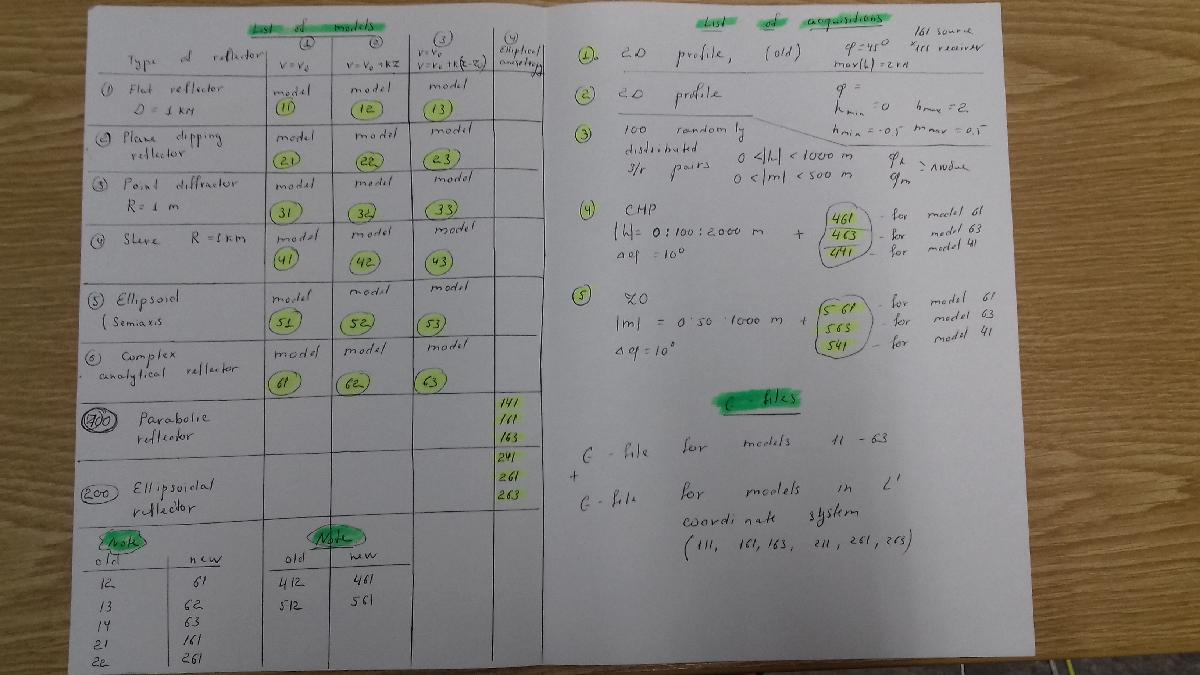

Model number (IJ) is a combination of reflector type (I) and velocity model (J): 

**Types of reflector:**

1) Flat reflector

2) Plane dipping reflector

3) Point diffractor

4) Sphere with R=1 km 

5) Ellipsoid

6) Complex analytical reflector

**Types of velocity model:**

1) constant: v = v0

2) constant gradient: v = v0 + k*z (z - depth)

3) constant + constant gradient: if (z < z0) : v = v0; else: v = v0 + k*(z-z0)

See all possible models is the table.

**Also it is possible to choose one of 5 acquisition geometries:**

1) a 2D profile

2) a 2D profile

3) 100 randomly distributed points

4) 3D CMP acquisition

5) 3D ZO acquisition

## Set model and acquisition

Note:

Accuracy of traveltime 10e-12

Accuracy of attributes 10e-10

model = 61;
acquisition = 2;

## Get model parameters

Get_model_parameters;        

## Get acquisition geometry

Get_model_acquisition_geometry;   
      

## Plot acquisition geometry

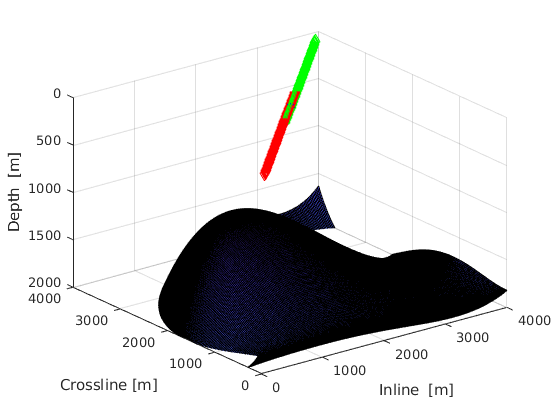

figure(1)
[XX, YY] = meshgrid(G.xx, G.yy);
[ZZ, ind] = Get_model_surface(XX,YY,model);
surf(XX,YY,ZZ); 
hold on
plot3(Xs(1,:),Xs(2,:),Xs(3,:), 'rv');
plot3(Xg(1,:),Xg(2,:),Xg(3,:), 'g^');
plot3(X0(1),X0(2),X0(3), 'b*');
axis([G.x0, G.mx, G.y0, G.my, G.z0, G.mz]);
xlabel('Inline  [m]'); 
ylabel('Crossline [m]'); 
zlabel('Depth  [m]'); 
view(3); 
set(gca, 'ZDir', 'reverse')

## Find stacking parameters

[ t0, w3, M3, N3 ] = Get_model_stacking_parameters( X0, model );

CRS_param.x0 = X0; 
CRS_param.t0 = t0; 
CRS_param.v0 = v0; 
CRS_param.w  = w3; 
CRS_param.M  = M3; 
CRS_param.N  = N3; 

save([mlibfolder '/CRS/models/model_' num2str(model) '_CRS_param.mat'], 'CRS_param'); 


either take (x,y) components and find wavefield attributes (reality):

w = w3(1:2, 1); 
N = N3(1:2, 1:2);
M = M3(1:2, 1:2);  
[ alpha, beta, KNIP, KN ] = my_A2P(v0, w, M, N);
 

or find wavefield attributes and make from them stacking parameters (theory):

% [ alpha, beta, KNIP3, KN3 ] = my_A3P(v0, w3, M3, N3);
% KNIP = KNIP3(1:2,1:2); 
% KN   = KN3  (1:2,1:2);
% [ w, M, N ] = my_P2A(v0, alpha, beta, KNIP, KN);

## Exact traveltimes

either download exact traveltimes

tti_ex = MLD([mlibfolder '/CRS/models/model_' num2str(model) '_traveltimes_for_acq_' num2str(acquisition) '.mat']);

or calculation exact traveltimes again

Note: computation of traveltime for model 63 is very time-consuming!!!

%tic
%tti_ex = Get_model_exact_traveltime(Xs, Xg, model);
%toc
%save([mlibfolder '/CRS/models/model_' num2str(model) '_traveltimes_for_acq_' num2str(acquisition) '.mat'], 'tti_ex'); 

## Traveltime approximations

HH = (Xg(1:2, :) - Xs(1:2,:))/2;
MM = (Xg(1:2, :) + Xs(1:2,:))/2;
MM(1,:) = MM(1,:) - X0(1); 
MM(2,:) = MM(2,:) - X0(2);

% CRS
tic
tti_crs  = Get_traveltime_3D_CRS (MM, HH, t0, w, M, N);
ctime.crs = toc; 
% DSR
tic
tti_dsr  = Get_traveltime_3D_DSR (MM, HH, t0, w, M, N);
ctime.dsr = toc; 
% nCRS
tic
tti_ncrs = Get_traveltime_3D_nCRS(MM, HH, t0, w, M, N);
tti_ncrs = real(tti_ncrs); 
ctime.ncrs = toc; 
% iCRS parabolic
tic
tti_icrs_par_LIA = Get_traveltime_3D_iCRS_par_LIA(MM, HH, t0, w, M, N, 10);
ctime.icrs_par_LIA = toc; 
% iCRS 1
tic
tti_icrs_el_LIA = Get_traveltime_3D_iCRS_el_LIA(MM, HH, t0, v0, w, M, N, 10);
ctime.icrs_el_LIA = toc; 
% iCRS 2
tic
tti_icrs_el_TIA = Get_traveltime_3D_iCRS_el_TIA(MM, HH, t0, v0, w, M, N, 10);
ctime.icrs_el_LTA = toc;

## RMS errors

err_rms_crs  = sqrt(sum(((tti_crs  - tti_ex)./tti_ex).^2)/100)*100;
err_rms_dsr  = sqrt(sum(((tti_dsr  - tti_ex)./tti_ex).^2)/100)*100;
err_rms_ncrs = sqrt(sum(((tti_ncrs - tti_ex)./tti_ex).^2)/100)*100;

for iter = 1:10
    err_rms_icrs_par_LIA(iter) = sqrt(sum(((tti_icrs_par_LIA(iter,:) - tti_ex)./tti_ex).^2)/100)*100;
    err_rms_icrs_el_LIA(iter)  = sqrt(sum(((tti_icrs_el_LIA(iter,:)  - tti_ex)./tti_ex).^2)/100)*100;
    err_rms_icrs_el_TIA(iter)  = sqrt(sum(((tti_icrs_el_TIA(iter,:)  - tti_ex)./tti_ex).^2)/100)*100;
end
err = [err_rms_crs, err_rms_dsr, err_rms_ncrs]

err =     1.5239    0.5713    0.0135



tti_icrs = tti_icrs_el_LIA(iter,:);

texac = reshape(tti_ex,length(hx),length(mx)); 
tcrs = reshape(tti_crs,length(hx),length(mx)); 
tncrs = reshape(tti_ncrs,length(hx),length(mx)); 
tdsr = reshape(tti_dsr,length(hx),length(mx)); 
ticrs = reshape(tti_icrs,length(hx),length(mx)); 

## Compate results

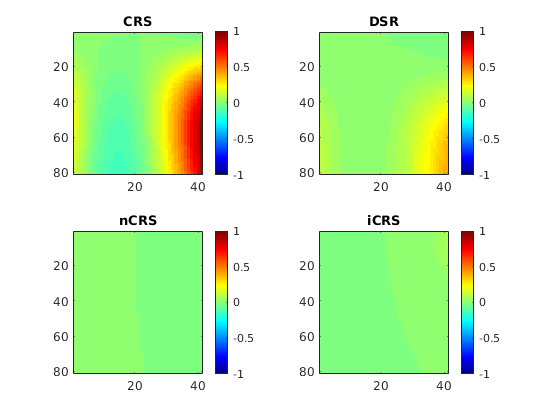

figure(2) 
subplot(2,2,1) 
imagesc( (tcrs - texac)./texac*100); 
title('CRS') 
caxis([-1 1])
colorbar
subplot(2,2,2) 
imagesc( (tdsr - texac)./texac*100); 
title('DSR') 
caxis([-1 1])
colorbar
subplot(2,2,3) 
imagesc( (tncrs - texac)./texac*100); 
title('nCRS') 
caxis([-1 1])
colorbar
subplot(2,2,4) 
imagesc( (ticrs - texac)./texac*100); 
title('iCRS') 
caxis([-1 1]) 
colormap('jet')
colorbar